clear all
clc

## Locations of Obstacles 

The first column contains the row indices, and the second column contains the column indices.

obsMat = [4 3; 5 3; 6 3; 7 3; 8 3; 9 3; 5 11; 6 11; 7 11; 8 11; 5 12; 6 12; 7 12; 8 12];

Initialize the robot positions.

sA0 = [2 2];
sB0 = [11 4];
sC0 = [3 12];
s0 = [sA0; sB0; sC0];
Ts = 0.1; % sample time 
Tf = 100; % simulation time
maxsteps = ceil(Tf/Ts); % Max Number of steps per episode
episode = 1; % initial training episodes
episodeMax = 5e5;% max training episodes


Open the Simulink model.

mdl = "ConsolidatedModelV6";
% open_system(mdl)

## Action space & Observation space

#### observation  and action 

% Define observation specifications.
obsSize = [12 12 4];
oinfo = rlNumericSpec(obsSize);
oinfo.Name = 'observations';

% Define action specifications.
numAct = 8;
% actionSpace = {0,1,2,3,4,5,6,7,8};
actionSpace = {1,2,3,4,5,6,7,8};
ainfo = rlFiniteSetSpec(actionSpace);
ainfo.Name = 'actions';


Specify the block paths for the agents.

blks = mdl + ["/Agent A (Red)","/Agent B (Green)","/Agent C (Blue)"];

Create the environment interface, specifying the same observation and action specifications for all three agents.

env = rlSimulinkEnv(mdl,blks,{oinfo,oinfo,oinfo},{ainfo,ainfo,ainfo});
env.ResetFcn = @(in) resetMap(in, obsMat);


## Create Agents

% random number generator
rng(0)

Choose Type of RL Agents

RLAgentType = inputdlg("Guide/ Agent 1 Reinforcement Learning Type (PPO/DQN/AC/SARSA): ", "Choices",[1 50])

RLAgentType = 1×1 cell array
    {'AC'}


RLAgentType = cell2mat(RLAgentType);
  switch RLAgentType

## PPO Agent

      case "PPO"
for idx = 1:3
    % Create actor deep neural network.
    actorNetWork = [
        imageInputLayer(obsSize,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(numAct,'Name','output')
        softmaxLayer('Name','action')];
    actorNetWork = dlnetwork(actorNetWork);
    
    % Create critic deep neural network.
    criticNetwork = [
        imageInputLayer(obsSize,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(1,'Name','output')];
    criticNetwork = dlnetwork(criticNetwork);
    
    % create actor and critic
    actor(idx) = rlDiscreteCategoricalActor(actorNetWork,oinfo,ainfo); %#ok<*SAGROW> 
    critic(idx) = rlValueFunction(criticNetwork,oinfo);
end

% optimizer options for the actor and critic.
actorOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'Algorithm','adam'...  % AMDAM Optimizer
    );
criticOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1,'Algorithm','adam'...  % AMDAM Optimizer
    );

% Specify the agent options 
opt = rlPPOAgentOptions(...
    'ActorOptimizerOptions',actorOpts,...
    'CriticOptimizerOptions',criticOpts,...
    'ExperienceHorizon',maxsteps,... % maxsteps = 1000
    'ClipFactor',0.2,...
    'EntropyLossWeight',0.01,...
    'MiniBatchSize',64,...
    'NumEpoch',3,...
    'AdvantageEstimateMethod','gae',...
    'GAEFactor',0.95,...
    'SampleTime',Ts,...
    'DiscountFactor',0.995);

% agents using the defined actors, critics, and options.
agentA = rlPPOAgent(actor(1),critic(1),opt);
agentB = rlPPOAgent(actor(2),critic(2),opt);
agentC = rlPPOAgent(actor(3),critic(3),opt);

## Deep Q-Learning Network Agent

      case "DQN"
  
          for idx = 1:3
    % Create actor deep neural network.
    criticNetwork = [
        imageInputLayer(obsSize,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(length(ainfo.Elements),'Name','output')];
    
    criticNetwork = dlnetwork(criticNetwork);

    % create  critic
     critic(idx) = rlVectorQValueFunction(criticNetwork,oinfo,ainfo);

    % optimizer options for the critic.
          end
 DQNOptiOpts= rlOptimizerOptions('LearnRate',1e-3, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );

opt = rlDQNAgentOptions(...
    'SampleTime',Ts,... event-based
    'UseDoubleDQN',true,...
    'CriticOptimizerOptions',DQNOptiOpts,... ADAM Optimizer with learning rate 0.001
    'ExperienceBufferLength',1e5,...  % replay buffer  
    'MiniBatchSize',128 ... sample batch size 
     );

opt.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
opt.EpsilonGreedyExploration.Epsilon = 0.9;
opt.EpsilonGreedyExploration.EpsilonMin = 0.05;


% agents using the defined critics, and options.
agentA = rlDQNAgent(critic(1),opt);
agentB = rlDQNAgent(critic(2),opt);
agentC = rlDQNAgent(critic(3),opt);
          

## Actor-Critic Agent

      case "AC"
for idx = 1:3
    % Create actor deep neural network.
    actorNetWork = [
        imageInputLayer(obsSize,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(numAct,'Name','output')
        softmaxLayer('Name','action')];
    actorNetWork = dlnetwork(actorNetWork);
    
    % Create critic deep neural network.
    criticNetwork = [
        imageInputLayer(obsSize,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(1,'Name','output')];
    criticNetwork = dlnetwork(criticNetwork);
    
    % create actor and critic
    actor(idx) = rlDiscreteCategoricalActor(actorNetWork,oinfo,ainfo); %#ok<*SAGROW> 
    critic(idx) = rlValueFunction(criticNetwork,oinfo);
end

% optimizer options for the actor and critic.
actorOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );
criticOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );

  

% opt = rlACAgentOptions(...
%     'ActorOptimizerOptions',actorOpts,...
%     'CriticOptimizerOptions',criticOpts,...
% % 'ExperienceHorizon',128,... 
%  %   'ClipFactor',0.2,...
% %     'EntropyLossWeight',0.01,...
% %     'MiniBatchSize',64,...
% %     'NumEpoch',3,...
% %     'AdvantageEstimateMethod','gae',...
% %     'GAEFactor',0.95,...
%     'SampleTime',Ts,...
%     'DiscountFactor',0.995);

opt = rlACAgentOptions(...
    'ActorOptimizerOptions',actorOpts,...
    'CriticOptimizerOptions',criticOpts,...
    'SampleTime',Ts,...
    'DiscountFactor',0.995);
% initOpt = rlAgentInitializationOptions;

% agents using the defined actors, critics, and options.
agentA = rlACAgent(actor(1),critic(1),opt);
agentB = rlACAgent(actor(2),critic(2),opt);
agentC = rlACAgent(actor(3),critic(3),opt);

# SARSA Agent

      case "SARSA"
         % Define observation specifications.
   SARSAobsSize = [12 12 4];
%    emptyCell = cell(12,12,4);
%    for l = 1:12
%        for j = 1:12
%        for i = 1:4
% emptyCell(l,j,i) = {[l j i]};
%        end
%        end
%    end
   for i = 1:576
       elmnts(1,i) = i;

   end
elmnts = elmnts';
   SARSAoinfo = rlFiniteSetSpec(elmnts);

   SARSAoinfo.Name = 'SARSA observations';
   env = rlSimulinkEnv(mdl,blks,{SARSAoinfo,SARSAoinfo,SARSAoinfo},{ainfo,ainfo,ainfo});
   env.ResetFcn = @(in) resetMap(in, obsMat);
          qTable = rlTable(SARSAoinfo,ainfo);
          
          for idx =1:3
         
          qFunction(idx) = rlQValueFunction(qTable,SARSAoinfo,ainfo);
          
          end
            
 criticOpts= rlOptimizerOptions('LearnRate',1e-3, ...
    'Algorithm','adam'...  % AMDAM Optimizer
    );

   opt = rlSARSAAgentOptions(...
    'CriticOptimizerOptions',criticOpts,...
    'SampleTime',Ts,...
    'DiscountFactor',0.995);
opt.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
opt.EpsilonGreedyExploration.Epsilon = 0.9;
opt.EpsilonGreedyExploration.EpsilonMin = 0.05;
% agents using the defined actors, critics, and options.
agentA = rlSARSAAgent(qFunction(1),opt);
agentB = rlSARSAAgent(qFunction(2),opt);
agentC = rlSARSAAgent(qFunction(3),opt);

# Q-Learning Agent

      case "Q"
 qTable = rlTable();

          
     for idx = 1:3
                  critic(idx) = rlQValueFunction(oinfo,ainfo)
     end

 opt = rlQAgentOptions("CriticOptimizerOptions","adam", ...
     "SampleTime",Tf)
 opt.EpsilonGreedyExploration.EpsilonDecay = 1e-4;
 opt.EpsilonGreedyExploration.Epsilon = 0.9;
 opt.EpsilonGreedyExploration.EpsilonMin = 0.05;


agentA = rlQAgent(critic(1),opt);
agentB = rlQAgent(critic(2),opt);
agentC = rlQAgent(critic(3),opt);

#  Deep Determinstic Policy Gradient

case "DDPG"
   % create DDPG agent action space
   DDPGact1Info = rlNumericSpec([1 1],'LowerLimit',0*ones(1,1),'UpperLimit',9*ones(1,1));
   DDPGact1Info.Name = "DDPG actions"
    env = rlSimulinkEnv(mdl,blks,{oinfo,oinfo,oinfo},{DDPGact1Info,DDPGact1Info,DDPGact1Info});
    env.ResetFcn = @(in) resetMap(in, obsMat);
   
    for idx =1:3
    %%%%%%%%%%%%% create actor network %%%%%%%%%%%%
    
 actorNetWork1 = [
     imageInputLayer(obsSize,'Normalization' ,'none' ,'Name' ,'observations')
 fullyConnectedLayer(64,"Name","Linear1")  
 reluLayer("Name","Relu1") 
 fullyConnectedLayer(64,"Name","Linear2") 
 reluLayer("Name","Relu2")
  fullyConnectedLayer(numAct,"Name","Linear3")
  softmaxLayer('Name','action')];
 actorNetWork1 = dlnetwork(actorNetWork1);
 
 
 analyzeNetwork(actorNetWork1)
 actorOpts = rlOptimizerOptions('LearnRate',1e-04,'GradientThreshold',1, ...
     'L2RegularizationFactor',1e-4,'Algorithm','adam');
 actor(idx) = rlContinuousDeterministicActor(actorNetWork1,oinfo,DDPGact1Info);
 
 %%%%%%%%%%%%  create critic network %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% create Observation Path
obsPath = [
    imageInputLayer(obsSize,'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','CriticStateFC1')
    reluLayer('Name', 'CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')];


% create Action Path
% actPath =[featureInputLayer(1,'Normalization','none','Name','action')
%     fullyConnectedLayer(64,'Name','CriticActionFC1','BiasLearnRateFactor',0)];

%create Common Path
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% add  Observation Path and Action Path
criticNetwork1 = layerGraph();
criticNetwork1 = addLayers(criticNetwork1,obsPath);
% criticNetwork1 = addLayers(criticNetwork1,actPath);
criticNetwork1 = addLayers(criticNetwork1,commonPath);
 
criticNetwork1 = connectLayers(criticNetwork1,'CriticStateFC2','add/in1');
% criticNetwork1 = connectLayers(criticNetwork1,'CriticActionFC1','add/in2');
criticNetwork1 = dlnetwork(criticNetwork1);  
  
criticOpts = rlOptimizerOptions('LearnRate',0.02,'GradientThreshold',1,...
    'L2RegularizationFactor',1e-4,"Algorithm","adam"); % critic optimisation option
critic(idx) = rlQValueFunction(criticNetwork1,oInfo,DDPGact1Info);  
    end
analyzeNetwork(criticNetwork1)  


 
% DDPG agent options
agent1Opts = rlDDPGAgentOptions('SampleTime',Ts,...
    'CriticOptimizerOptions',criticOpts,... %% Critic Options
    'ActorOptimizerOptions',actorOpts,... %% Actor Options
    'ExperienceBufferLength',1e6,... %% Replay Buffer 
    'DiscountFactor',0.99,...
    'MiniBatchSize',128)


  % create DDPG Agent

  agentA = rlDDPGAgent(actor(1),critic(1),agent1Opts);
  agentB = rlDDPGAgent(actor(2),critic(2),agent1Opts);
  agentC = rlDDPGAgent(actor(3),critic(3),agent1Opts);

% End of Switch 
  end

## Training 

Training Options

if RLAgentType == "PPO"
    trainOpts = rlMultiAgentTrainingOptions(...
    "AgentGroups",{[1,2,3]},...
    "LearningStrategy","centralized",...
    'MaxEpisodes',20,...
    'MaxStepsPerEpisode',maxsteps,...
    'Plots','training-progress',...
    'ScoreAveragingWindowLength',100,...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',80); 
else
    trainOpts = rlMultiAgentTrainingOptions(...
    "LearningStrategy","decentralized",...
    'MaxEpisodes',20,...
    'MaxStepsPerEpisode',maxsteps,...
    'Plots','training-progress',...
    'ScoreAveragingWindowLength',100,...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',80); 
end

Start Training

doTraining = inputdlg("Do training (true or false): ", "Choices",[1 50])

doTraining = 1×1 cell array
    {'true'}


doTraining = cell2mat(doTraining);
% doTraining = true;
if doTraining
result = train([agentA,agentB,agentC],env,trainOpts);

## Simulation

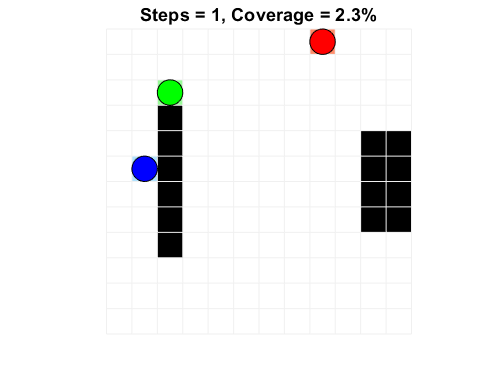

Error using rl.train.marl.MultiAgentTrainer/run
Simulation aborted

Error in rl.train.TrainingManager/train (line 429)
            run(trainer);

Error in rl.train.TrainingManager/run (line 218

else
rng(0) % reset the random seed
simOpts = rlSimulationOptions('MaxSteps',maxsteps);
experience = sim(env,[agentA,agentB,agentC],simOpts);
end